addpath('Classes')
addpath('Simulink Models')
addpath('Functions')

%Make sure symprefs are set correctly for this script
sympref('MatrixWithSquareBrackets',true);
sympref('AbbreviateOutput', false);
sympref('FloatingPoint',true);
sympref('TypesetOutput',true);


# Output Sliding Mode Control Research Script

%Create a variable definitions object if one does not already exist. 
if (~exist('VDefs', 'var')) 

    VDefs = Var_Defs;  %Create an object of the class Var_Defs

end 

%Create a u-joint Kinematics object if one does not already exist. 
if (~exist('UJ_Knmtcs', 'var')) 

    UJ_Knmtcs = UJ_Knmtcs(VDefs); %Create an object of the class UJ_Knmtcs
    UJ_Knmtcs.derive_all; %Run all of its derivation functions

end 

%Create a ball-plate kinematics object if one does not already exist. 
if (~exist('BP_Knmtcs', 'var')) 

    BP_Knmtcs = BP_Knmtcs(VDefs, UJ_Knmtcs); %Create an object of the class BP_Knmtcs
    BP_Knmtcs.Derive_Both; %Derive all the kinematic equations for the ball-plate system
end 

%Create a ball-plate kinetics object if one does not already exist. 
if (~exist('BP_Kinetics', 'var')) 

    BP_Kinetics = BP_Kinetics(VDefs, UJ_Knmtcs, BP_Knmtcs); %Create an object of the class BP_Kinetics
    BP_Kinetics.Derive_NL_EOMs; %Derive the nonlinear equations of motion for the ball-plate system
    BP_Kinetics.Num_Params_n_Assumptions; %Input numerical parameters and assumptions
end 


%Create a nonlinear decoupled EOMs object if one does not already exist. 
if (~exist('NL_Dcpld_EOMs', 'var')) 

    NL_Dcpld_EOMs = NL_Dcpld_EOMs(VDefs, BP_Kinetics); %Create an object of the class NL_Dcpld_EOMs
    NL_Dcpld_EOMs.Num_Params;
end

%Define a few symbolic variables to be used
syms lambda_1 lambda_2 S_1 S_2 S_dot_1 S_dot_2 u_1 u_2 u_hat_1 u_hat_2 K_s


## System 1 - x direction

### Sliding Surface for global x location of the ball 


$$\begin{array}{l}

S_1 = e_{\dot{x}} + \lambda_1 \, e_x\\

\end{array}

$$


e_x = VDefs.x_s - VDefs.x;
e_x_dot = VDefs.x_dot_s - VDefs.x_dot;
S1_eqn = S_1 ==  e_x_dot + lambda_1*(e_x)

$$S1\_eqn = S_{1}={\dot{x}}_{s}-\dot{x}-\lambda_{1}\,\left(x-x_{s}\right)$$

xdd = rhs(isolate(NL_Dcpld_EOMs.Num_SumMBall_x, VDefs.x_ddot));

In the sum of moments for the ball, call $sin(\beta)~u_1$. 

xdd = subs(xdd, sin(VDefs.beta), u_1)

$$xdd = 0.7143\,x\,{\dot{\beta }}^{2}-0.1113\,\ddot{\beta }+7.0071\,u_{1}$$

Sd1_eqn = S_dot_1 == VDefs.x_ddot_s - xdd + lambda_1*(e_x_dot)

$$Sd1\_eqn = {\dot{S}}_{1}=-0.7143\,x\,{\dot{\beta }}^{2}+0.1113\,\ddot{\beta }-7.0071\,u_{1}+{\ddot{x}}_{s}-\lambda_{1}\,\left(\dot{x}-{\dot{x}}_{s}\right)$$

### Nullifying $\mathbf{sin(\beta)}$ Input 

Finding the input, $u_1(\beta) = sin(\beta)$, required to zero out the derivative of the sliding surface. Allows us to determine wether or not the sliding surface is attractive given the angular constraints (if nullifying input exceeds the constraints, it may not be possible to make the surface attractive). 

u_hat_1_eqn = u_hat_1 == rhs(isolate(subs(Sd1_eqn, S_dot_1, 0),u_1))

$$u\_hat\_1\_eqn = {\hat{u}}_{1}=-0.1019\,x\,{\dot{\beta }}^{2}+0.0159\,\ddot{\beta }+0.1427\,{\ddot{x}}_{s}-0.1427\,\lambda_{1}\,\left(\dot{x}-{\dot{x}}_{s}\right)$$


%Test Nullifying Input
simplify(subs(rhs(Sd1_eqn ), u_1, rhs(u_hat_1_eqn)))

$$ans = 0$$

### Lyapunov Function and Switching Law


$$\begin{array}{l}

V_1 = \frac{S_1^^2}{2}\\

\dot{V}_1 = S_1 \, \dot{S}_1

\end{array}$$


Vd1 = S_1*rhs(Sd1_eqn)

$$Vd1 = -S_{1}\,\left(0.7143\,x\,{\dot{\beta }}^{2}-0.1113\,\ddot{\beta }+7.0071\,u_{1}-{\ddot{x}}_{s}+\lambda_{1}\,\left(\dot{x}-{\dot{x}}_{s}\right)\right)$$


b_S1d = double(equationsToMatrix(rhs(Sd1_eqn), u_1)) %Input matrix for u_1 in S1dot equation

b_S1d = -7.0071


switching_law1 = -K_s/b_S1d*sign(S_1) %

$$switching\_law1 = 0.1427\,K_{s}\,\mathrm{sign}\left(S_{1}\right)$$

## System 2 - y direction

### Sliding Surface for global x location of the ball 


$$\begin{array}{l}

S_2 = e_{\dot{y}} + \lambda_2 \, e_y\\

\end{array}

$$


e_y = VDefs.y_s - VDefs.y;
e_y_dot = VDefs.y_dot_s - VDefs.y_dot;
S2_eqn = S_2 ==  e_y_dot + lambda_2*(e_y)

$$S2\_eqn = S_{2}={\dot{y}}_{s}-\dot{y}-\lambda_{2}\,\left(y-y_{s}\right)$$

ydd = rhs(isolate(NL_Dcpld_EOMs.Num_SumMBall_y, VDefs.y_ddot));

In the sum of moments for the ball, call $sin(\gamma)~u_2$. 

ydd = subs(ydd, sin(VDefs.gamma), u_2)

$$ydd = 0.7143\,y\,{\dot{\gamma }}^{2}+0.1113\,\ddot{\gamma }-7.0071\,u_{2}$$

Sd2_eqn = S_dot_2 == VDefs.y_ddot_s - ydd + lambda_2*(e_y_dot)

$$Sd2\_eqn = {\dot{S}}_{2}=-0.7143\,y\,{\dot{\gamma }}^{2}-0.1113\,\ddot{\gamma }+7.0071\,u_{2}+{\ddot{y}}_{s}-\lambda_{2}\,\left(\dot{y}-{\dot{y}}_{s}\right)$$

### Nullifying $\mathbf{sin(\gamma)}$ Input 

Finding the input, $u_2(\gamma) = sin(\gamma)$, required to zero out the derivative of the sliding surface. Allows us to determine wether or not the sliding surface is attractive given the angular constraints (if nullifying input exceeds the constraints, it may not be possible to make the surface attractive). 

u_hat_2_eqn = u_hat_2 == rhs(isolate(subs(Sd2_eqn, S_dot_2, 0),u_2))

$$u\_hat\_2\_eqn = {\hat{u}}_{2}=0.1019\,y\,{\dot{\gamma }}^{2}+0.0159\,\ddot{\gamma }-0.1427\,{\ddot{y}}_{s}+0.1427\,\lambda_{2}\,\left(\dot{y}-{\dot{y}}_{s}\right)$$


%Test Nullifying Input
simplify(subs(rhs(Sd2_eqn ), u_2, rhs(u_hat_2_eqn)))

$$ans = 0$$

### Lyapunov Function and Switching Law


$$\begin{array}{l}

V_2 = \frac{S_2^^2}{2}\\

\dot{V}_2 = S_2 \, \dot{S}_2

\end{array}$$


Vd2 = S_2*rhs(Sd2_eqn)

$$Vd2 = -S_{2}\,\left(0.7143\,y\,{\dot{\gamma }}^{2}+0.1113\,\ddot{\gamma }-7.0071\,u_{2}-{\ddot{y}}_{s}+\lambda_{2}\,\left(\dot{y}-{\dot{y}}_{s}\right)\right)$$


b_S2d = double(equationsToMatrix(rhs(Sd2_eqn), u_2)) %Input matrix for u_2 in S2dot equation

b_S2d = 7.0071


switching_law2 = -K_s/b_S2d*sign(S_2)

$$switching\_law2 = -0.1427\,K_{s}\,\mathrm{sign}\left(S_{2}\right)$$

## Desired Trajectory in x and y

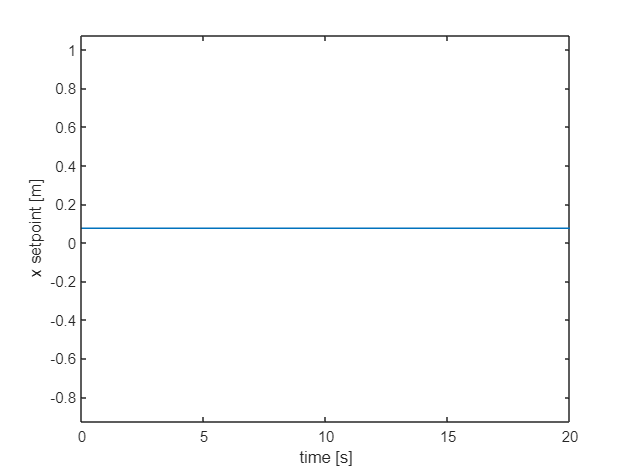

%Ideal trajectory parameters
r_sim = .15; % radius of trajectory [m] Touch screen is about 30 cm wide
% freq = 1/9; %rotations per second: 1/9 for octofolium is about as fast as it gets
% freq = 1/6; %rotations per second:  1/6 for quadrifolium is about as fast as it gets
freq = 1/4;
omega_sim =  2*pi*freq; %angular frequency of circular trajectory 


%Specify initial conditions and compute initial outputs
x_0 = 1/2*[r_sim; 0; 0; 0; r_sim; 0; 0; 0]; %As if the ball was at rest in the center of the plate - the control objective of any regulator designed for the system


%Ideal trajectory symfuns
%Figure 8
% des_traj_sym_x(VDefs.t) = r_sim*sin(omega_sim*VDefs.t);
% des_traj_sym_y(VDefs.t) = r_sim*sin(omega_sim*VDefs.t)*cos(omega_sim*VDefs.t);

%Simple STAY AT THE ICs SETPOINT for tuning inner angular loops
des_traj_sym_x(VDefs.t) = x_0(1);
des_traj_sym_y(VDefs.t) = x_0(5);

%Rose curve specified by k
n = 1;
% d = 1;
% k = n/d
% des_traj_sym_y1(VDefs.t) = r_sim*cos(k*omega_sim*VDefs.t)*cos(omega_sim*VDefs.t);
% des_traj_sym_y2(VDefs.t) = r_sim*cos(k*omega_sim*VDefs.t)*sin(omega_sim*VDefs.t);


%Overlay first order smoothing functions
Tau = 3; %Time constant for first order response (3 has been working well at the 1.3 Hz)


%Trajectory symfuns with first order smoothing overlayed and a smooth transition from the
%initial conditions
des_traj_sym_x(VDefs.t) = des_traj_sym_x(VDefs.t)*(1-exp(-VDefs.t/Tau)) + x_0(1)*exp(-VDefs.t/Tau);
des_traj_sym_y(VDefs.t) = des_traj_sym_y(VDefs.t)*(1-exp(-VDefs.t/Tau)) + x_0(5)*exp(-VDefs.t/Tau);

fplot(des_traj_sym_x) 
xlim([0 2*pi/omega_sim*5]); 
ylabel('x setpoint [m]')
xlabel('time [s]')

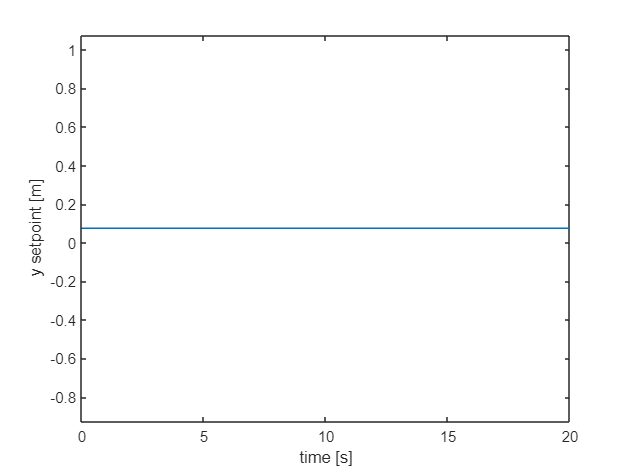


fplot(des_traj_sym_y) 
xlim([0 2*pi/omega_sim*5]); 
ylabel('y setpoint [m]')
xlabel('time [s]')


%Trajectory's derivatives
des_traj_sym_dot_x(VDefs.t) = diff(des_traj_sym_x(VDefs.t),VDefs.t);
des_traj_sym_dot_y(VDefs.t) = diff(des_traj_sym_y(VDefs.t),VDefs.t);
des_traj_sym_ddot_x(VDefs.t) = diff(des_traj_sym_x(VDefs.t),VDefs.t,2);
des_traj_sym_ddot_y(VDefs.t) = diff(des_traj_sym_y(VDefs.t),VDefs.t,2);

%x_s_vec and y_s_vec
des_traj_sym_x = [des_traj_sym_x;des_traj_sym_dot_x;des_traj_sym_ddot_x];
des_traj_sym_y = [des_traj_sym_y;des_traj_sym_dot_y;des_traj_sym_ddot_y];

## Numerical Control Parameters


%Choose numerical lambdas 
lambda_1_num = 1/3; 
lambda_2_num = lambda_1_num;

%Max torque
Tmax = VDefs.Tmax; % [Nm] Comes from rated torque of Scott's motors and the gear ratio assumption

%Max angle
Angle_max = deg2rad(20) %Used to saturate the requested angular setpoint for the inner loop

Angle_max = 0.3491


%Inner loop PI gains (Beta and Gamma)
Kp_Beta = 20;
Ki_Beta = 30;
Kp_Gamma = 20;
Ki_Gamma = 30;

%Switching gain
K_switch = sin(deg2rad(20))/3; %Not a saturation on the input, only aggressiveness tuning

%Boundary layer size
S_BL_value = 0.001; %.001 was good for 1/3 and slower trajectory frequency

%Boundary Layer Gain
BL_gain = (K_switch)/S_BL_value; %To prevent fast switches at the border of the boundary layer, need to have the cuttoff angle be equal to the switching angle
%Gain in the BL is then coupled to the size of the boundary layer. 

## Generate all the Necessary Matlab Function Blocks in Simulink

%Replace the definition of the various MATLAB function blocks with a
%function generated from symbolic functions in the dual sliding surface control
%derivations

%% System 1 MATLAB Function Blocks

% Compute nullifying input u_1
sim_path_string = strcat('Angular_Input_Sliding_Mode','/Controller x dimension/Nullifying Input');
load_system('Angular_Input_Sliding_Mode');
input_chars = {'x' 'x_dot' 'beta_dot' 'beta_ddot' 'x_dot_s' 'x_ddot_s'};
matlabFunctionBlock(sim_path_string, subs(rhs(u_hat_1_eqn), lambda_1, lambda_1_num)  , 'FunctionName', 'u_hat_1','Vars',input_chars, 'Outputs', {'T_hat_beta'})

% %% System 2 MATLAB Function Blocks

% Compute nullifying torque T_hat_gamma
sim_path_string = strcat('Angular_Input_Sliding_Mode','/Controller y dimension/Nullifying Input');
load_system('Angular_Input_Sliding_Mode');
input_chars = {'y' 'y_dot' 'gamma_dot' 'gamma_ddot' 'y_dot_s' 'y_ddot_s'};
matlabFunctionBlock(sim_path_string, subs(rhs(u_hat_2_eqn), lambda_2, lambda_2_num)  , 'FunctionName', 'u_hat_2','Vars',input_chars, 'Outputs', {'T_hat_gamma'})

%%Trajectory Setpoints 

%x direction
sim_path_string = strcat('Angular_Input_Sliding_Mode','/global_x_Setpoint_Function');
load_system('Angular_Input_Sliding_Mode');
matlabFunctionBlock(sim_path_string, des_traj_sym_x,'FunctionName', 'y1_setpoint')

%y direction
sim_path_string = strcat('Angular_Input_Sliding_Mode','/global_y_Setpoint_Function');
load_system('Angular_Input_Sliding_Mode');
matlabFunctionBlock(sim_path_string, des_traj_sym_y,'FunctionName', 'y2_setpoint')

%Replace the definition of the "Plant_Function" MATLAB function block with a
%function generated from obj.plant symbolic function
sim_path_string = strcat('Angular_Input_Sliding_Mode','/Plant/Plant_Function');
load_system('Angular_Input_Sliding_Mode');
%Generate a matlab function from the linearized plant model
input_chars = {'x', 'x_dot', 'beta', 'beta_dot','y', 'y_dot', 'gamma', 'gamma_dot', 'T_beta', 'T_gamma' };
matlabFunctionBlock(sim_path_string, rhs(BP_Kinetics.NL_NumEOMs), 'FunctionName', 'xdot','Vars',input_chars)


## Simulate the Output Sliding Mode Controller

%Specify simulation time
tspan = [0 2*pi/omega_sim*5];

simout_Ang_In_SM = sim('Angular_Input_Sliding_Mode')

Invalid setting in 'Angular_Input_Sliding_Mode/Controller x dimension/Constant' for parameter 'Value'.

Caused by:
    Error using Angular_Input_Sliding_Mode_Control (line 209)
    Error evaluating parameter 'Value' in '

## Plot some stuff

figure
plot(simout_Ang_In_SM .tout,simout_Ang_In_SM .y1,simout_Ang_In_SM .tout,simout_Ang_In_SM .y1_s_vec(:,1))  

### Animate Responses

% n = 1;
% t_window = 2*pi/omega_sim*d*n; %Print n cycles worth of trajectory history
% Animate_Response(simout_Ang_In_SM .y1,simout_Ang_In_SM .y1_s_vec(:,1),...
%     simout_Ang_In_SM .y2,simout_Ang_In_SM .y2_s_vec(:,1),simout_Ang_In_SM .tout,25,'Output_y1y2_try.gif', r_sim, t_window)
% 
% Animate_Response(simout_Ang_In_SM .x(:,1),simout_Ang_In_SM .y1_s_vec(:,1),...
%     simout_Ang_In_SM .x(:,5),simout_Ang_In_SM .y2_s_vec(:,1),simout_Ang_In_SM .tout,25,'States_xy_try.gif', r_sim, t_window)

%view_vec = 2;
% Animate_Response_3D(simout_Ang_In_SM .x,simout_Ang_In_SM .tout,25,'try_3D_tpdwnView.gif',VDefs, view_vec)
view_vec = [140 40];
Animate_Response_3D(simout_Ang_In_SM .x,simout_Ang_In_SM .tout,25,'try_3D_angView.gif',VDefs, view_vec)